# Documentation and visualization

## Generate stf (steering information)

The  - `generateStf.m` function creates the seed coordinates needed for dose calculation. It takes three objects input arguments (no values are assigned inside the function):

- Information about the ct voxels `ct`

- The classification of these voxels into different organs and tissue` cst`

- Informaion about the radiation treatment plan` pln`

It the output is the `stf`  struct with the following fields: 

- `targetVolume`:                 voxel coordnates of target

- `template`:                         4xN array with 2D template and 3D template (4th row just ones)

- `radiationMode`:               string `'brachy'`

- `numOfNeedles:        total number of needles (= number of template holes)`

- `numOfSeedsPerNeedle`:   number of seeds in each needle

- `seedPoints`:                     1D array with seed position component stored in fields `x,y,z`

### Initial visualization of seed points

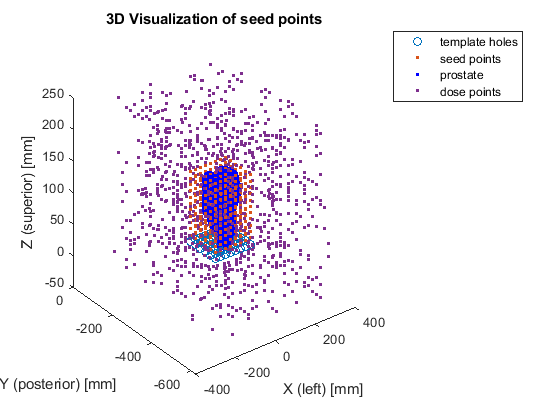

clf
% plot template
template3D = stf.template.template3D;
Template = plot3(template3D(1,:),template3D(2,:),template3D(3,:),'o','DisplayName', 'template holes');
legend(Template(:))
hold on

% plot 3D seed positions
SeedPoints = plot3(stf.seedPoints.x,stf.seedPoints.y,stf.seedPoints.z,'.','DisplayName', 'seed points');
title( '3D Visualization of seed points')
xlabel('X (left) [mm]')
ylabel('Y (posterior) [mm]')
zlabel('Z (superior) [mm]')

% plot 3d VOI points
TargX = stf.targetVolume.Xvox;
TargY = stf.targetVolume.Yvox;
TargZ = stf.targetVolume.Zvox;
Prostate = plot3(TargX,TargY,TargZ,'.', 'Color','b','DisplayName', 'prostate');

% plot random grid points
pltDoseGrid = 1; %true or false
fraction =  0.1; % random fraction of grid points to plot, [0,1]
if pltDoseGrid && exist('dij',"var")
    [x,y,z] = meshgrid(dij.doseGrid.x,dij.doseGrid.y,dij.doseGrid.z);
    randIndex = rand(size(reshape(x,[],1)))<fraction;
    x = reshape(x,[],1);
    y = reshape(y,[],1);
    z = reshape(z,[],1);
    dosX = x(randIndex);
    dosY = y(randIndex);
    dosZ = z(randIndex);
   
    plot3(dosX,dosY,dosZ,'.','DisplayName', 'dose points')
end

hold off;

% clear workspace
clear template3D TargX TargY TargZ Prostate SeedPoints Template x y z dosX dosY dosZ fraction pltDoseGrid randIndex

## Generate dij (dose matrix calculation)

The `-calcDose.m` - Function gets the following inputs:

- ct

- stf

- pln

- cst

The output is the `dij` struct with the following fields

- dose grid:                             resolution, dimentions, grid coordinates

- ct grid:                                  resolution, dimentions, grid coordinates

- numOfNeedles                    

- numOfSeedsPerNeedle

- pysicalDoseMatrix                physicalDose

### Layerwise visualization of dose 

D = dij.physicalDose{1,1};
weight = resultGUI.wUnsequenced;
%weight(502) = 1;
Dose = D*weight;
P = reshape(Dose,[length(dij.doseGrid.y),length(dij.doseGrid.x) ,length(dij.doseGrid.z)]);
slice =1

slice = 1

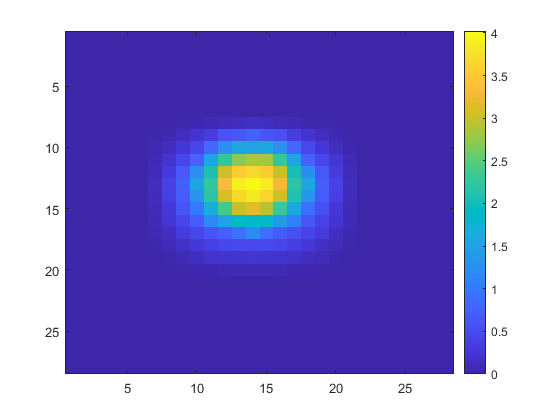

image(P(:,:,slice),'CDataMapping','scaled')
colorbar